# Trabalho de EE-254 (Controle Preditivo): Parte 3

**Observação:** Este trabalho deve ser realizado **sem o uso do MPT Toolbox.**

Considere o seguinte sistema de dois carros acoplados por uma mola:

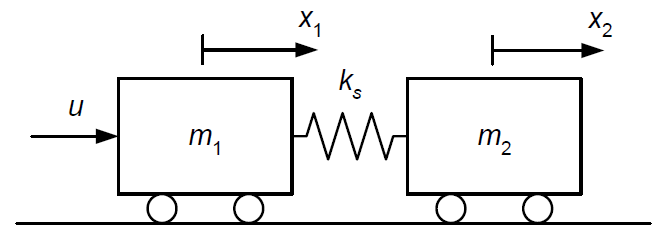

com deslocamentos $x_1$, $x_2$ definidos de modo que a mola esteja relaxada quando $x_1 = x_2$.  

A dinâmica deste sistema, a tempo contínuo, é descrita pelas seguintes equações:


$$m_1 \ddot{x}_1(t) = u(t) + k_s \big[\, x_2(t) - x_1(t) \,\big] $$



$$m_2 \ddot{x}_2(t) = - k_s \big[\, x_2(t) - x_1(t) \,\big]$$
 

que podem ser colocadas na forma 


$$\dot{x}(t) = A_c x(t) + B_c u(t) $$


com $x_3 = \dot{x}_1$, $x_4 = \dot{x}_2$ e

$A_c =
\left[
  \begin{array}{cccc}
    0 & 0 & 1 & 0 \\[4pt]
    0 & 0 & 0 & 1 \\[4pt]
    -k_s/m_1 & k_s/m_1 & 0 & 0 \\[4pt]
    k_s/m_2 & -k_s/m_2 & 0 & 0 \\
  \end{array}
\right]$, $B_c =
\left[
  \begin{array}{c}
    0 \\[4pt]
    0 \\[4pt]
    1/m_1 \\[4pt]
    0 \\
  \end{array}
\right]$

Neste trabalho, serão adotados os seguintes valores para os parâmetros do modelo:

$m_1 = 5$ kg, $m_2 = 3$ kg, $k_s = 10$ N/m, $g = 9\text{,}8$ m/s${}^2$

que resultam nas matrizes $A_c$, $B_c$ definidas no código abaixo:

clear, clc, close all
m1 = 5; m2 = 3; ks = 10; g = 9.8;
Ac = [0 0 1 0;
      0 0 0 1;
      -ks/m1 ks/m1 0 0;
      ks/m2 -ks/m2 0 0];
Bc = [0;0;1/m1;0];

A variável a ser controlada será o deslocamento do segundo carro, isto é, $y = x_2$. Essa é uma equação de saída da forma $y(t) = C x(t)$ com 

C = [0 1 0 0];


A tarefa de controle consiste em rastrear uma referência $r(t)$ constante por partes, com valor alternando entre $+$1 m e $-$1 m, respeitando a restrição de que a deformação da mola e o controle (ambos em módulo) não ultrapassem 0,05 m e 2 N, respectivamente.

O código abaixo obtém as matrizes $A$ e $B$ da equação de estado discretizada:


$$x(k+1) = A x(k) + B u(k)$$


considerando que o controle seja aplicado por meio de um segurador de ordem zero com período de amostragem $T = 0\text{,}2$ s.

T = 0.2;
[A,B] = c2dm(Ac,Bc,[],[],T,'zoh');

Dado um valor $\bar{r}$ para a referência, os respectivos valores de equilíbrio para o estado e o controle são determinados por meio das expressões $\bar{x} = N_x \bar{r}$ e $\bar{u} = N_u \bar{r}$, com $N_x$ e $N_u$ obtidos com o uso do código abaixo.

aux = inv([(A - eye(4)) B;C 0])*[0;0;0;0;1];
Nx = aux(1:4)

Nx =     1.0000
    1.0000
    0.0000
    0.0000


Nu = aux(5)

Nu = 2.7756e-15

### Parametrização de $\mathcal{O}_\infty$ com respeito a $\bar{r}$

As restrições de estado e controle podem ser expressas na forma $S_x x(k) \leq b_x$, $S_u u(k) \leq b_u$ com $S_x, b_x, S_u, b_u$definidas no código abaixo.

% Deformação da mola: -0.05 <= x1 - x2 <= 0.05
Sx = [1 -1 0 0;-1 1 0 0];
bx = [0.05;0.05];
% Controle: -2 <= u <= 2
Su = [1;-1];
bu = [2;2];

Considere um controlador DLQR com ganho $K$obtido da seguinte forma: 

q1 = 10; q2 = 10; q3 = 1; q4 = 1; q5 = 100;
Q = [q1 + q5 -q5 0 0; -q5 q2 + q5 0 0; 0 0 q3 0; 0 0 0 q4];
R = 1;
[K,P] = dlqr(A,B,Q,R);

%AULA 5 SLIDE 27
% P = Q + K^t * R * K + Af^t * P * Af
% 

lembrando que a matriz $P$ é a solução positivo-definida da equação algébrica de Riccati. Suponha ainda que a lei de controle DLQR seja empregada na forma $u(k) = - K \big[\, x(k) - \bar{x} \,\big] + \bar{u}$. Considerando que a referência seja constante, ou seja, $r(k+1) = r(k) = \bar{r}$, pode-se descrever a dinâmica de malha fechada por meio de uma equação da forma $\chi(k+1) = A_{\chi,f} \chi(k)$, em que

$\chi(k) = 
\left[
  \begin{array}{c}
    x(k) \\[4pt]
    r(k) \\
  \end{array}
\right]$, $A_{\chi,f} = 
\left[
  \begin{array}{cc}
    A_f & B(KN_x + N_u) \\[4pt]
    0_{q \times n} & I_{q \times q} \\
  \end{array}
\right]$

com $A_f = (A-BK)$.

**(1,0 ponto)** Digite no espaço abaixo um código para construção da matriz $A_{\chi,f}$.

Af = A - B*K

Af =     0.9381    0.0472    0.1631    0.0039
    0.0652    0.9346    0.0040    0.1956
   -0.6106    0.4647    0.6207    0.0513
    0.6382   -0.6415    0.0579    0.9348


% uk = -K*(xk - xbar)
% rk = rbar %[1 -1]

n = 4 

n = 4

q = 1

q = 1




I = eye(q)

I = 1


Achif11 = Af

Achif11 =     0.9381    0.0472    0.1631    0.0039
    0.0652    0.9346    0.0040    0.1956
   -0.6106    0.4647    0.6207    0.0513
    0.6382   -0.6415    0.0579    0.9348


Achif12 = B*(K*Nx + Nu)

Achif12 =     0.0147
    0.0002
    0.1459
    0.0032


Achif21 = zeros(q, n)

Achif21 =      0     0     0     0


Achif22 = I

Achif22 = 1

Achif = [Achif11 Achif12; Achif21 Achif22]

Achif =     0.9381    0.0472    0.1631    0.0039    0.0147
    0.0652    0.9346    0.0040    0.1956    0.0002
   -0.6106    0.4647    0.6207    0.0513    0.1459
    0.6382   -0.6415    0.0579    0.9348    0.0032
         0         0         0         0    1.0000


A fim de determinar o conjunto $\mathcal{O}_{\chi,\infty}$ para o estado $\chi(k)$, pode-se definir o seguinte vetor de variáveis sujeitas a restrições:


$$\psi(k) =
\left[
  \begin{array}{c}
    x(k) \\[4pt]
    u(k) \\[4pt]
    \bar{x} \\[4pt]
    \bar{u} \\
  \end{array}
\right] 
=
\Gamma \chi(k)$$


sendo


$$\Gamma = \left[
  \begin{array}{cc}
    I_{n \times n} & 0_{n \times q} \\[4pt]
    -K & (KN_x + N_u) \\[4pt]
    0_{n \times n} & N_x \\[4pt]
    0_{p \times n} & N_u \\
  \end{array}\right]
$$


As restrições podem então ser colocadas na forma $S_\psi \psi(k) \leq b_\psi$, com


$$S_\psi = \left[
  \begin{array}{cccc}
    {S_x} & 0_{n \times p} & 0_{n \times n} & 0_{n \times p} \\[4pt]
    0_{p \times n} & {S_u} & 0_{p \times n} & 0_{p \times p} \\[4pt]
    0_{n \times n} & 0_{n \times p} & {S_x} & 0_{n \times p} \\[4pt]
    0_{p \times n} & 0_{p \times p} & 0_{p \times n} & {S_u} \\
  \end{array}
\right],\;\;
b_\psi =
\left[
  \begin{array}{c}
    b_x \\[4pt]
    b_u \\[4pt]
    b_x - \epsilon_x \\[4pt]
    b_u - \epsilon_u \\
  \end{array}
\right]
$$


e $\epsilon_x$, $\epsilon_u$ vetores de constantes positivas, de modo a impor que $\bar{x}$ e $\bar{u}$ estejam no interior dos respectivos conjuntos de valores admissíveis.

**(1,0 ponto)** Escolha valores convenientes para $\epsilon_x$, $\epsilon_u$ e digite no espaço abaixo um código para construção de $\Gamma, S_\psi, b_\psi$.

% epsilon x e u devem-se estar dentro do conjunto
epsilon_x =  1e-6*ones(size(Sx,1),1)

epsilon_x = 1.0e-06 *

    1.0000
    1.0000


epsilon_u= 1e-6*ones(size(Su,1),1)

epsilon_u = 1.0e-06 *

    1.0000
    1.0000



n = 4

n = 4

p = 1

p = 1



bpsi =  [bx;bu;bx-epsilon_x;bu-epsilon_u]

bpsi =     0.0500
    0.0500
    2.0000
    2.0000
    0.0500
    0.0500
    2.0000
    2.0000



Gamma = [eye(n) zeros(n,q);
            -K (K*Nx + Nu);
            zeros(n,n) Nx;
            zeros(p,n) Nu]

Gamma =     1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0
   -5.6915    1.9960   -8.6130    0.3054    3.6955
         0         0         0         0    1.0000
         0         0         0         0    1.0000
         0         0         0         0    0.0000
         0         0         0         0    0.0000
         0         0         0         0    0.0000




Spsi = blkdiag(Sx,Su,Sx,Su);

%{
Spsi1 = [Sx zeros(n,p) zeros(n,n) zeros(n,p)]
Spsi2 = [zeros(p,n) Su zeros(p,n) zeros(p,p)]
Spsi3 = [zeros(n,n) zeros(n,p) Sx zeros(n,p)]
Spsi4 = [zeros(p,n) zeros(p,p) zeros(p,n) Su]

Spsi = [Spsi1; Spsi2; Spsi3; Spsi4]
%  diag, horzcat, vertcat
% spdiags, triu, tril, blkdiag.
%}

**(1,0 ponto)** Empregando a função `determina_oinf.m` disponibilizada, obtenha o conjunto $\mathcal{O}_{\chi,\infty} = \{\chi : S_o x \leq b_o \}$.

% Insira seu código aqui

x0 = [-1;-1;0;0]; % Condição inicial
k=1;
max_iter =100;
tol=1e-6

tol = 1.0000e-06


[So, bo] = determina_oinf(Achif, Gamma, Spsi, bpsi, max_iter, tol);

Iteração 1 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 2 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 3 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 4 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 5 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Opti

**Observação:** Caso não tenha sido possível completar este item, carregue o arquivo `ochi_inf.mat` disponibilizado.

**(1,0 ponto)** Com base em $S_o$, obtenha $S_f$, $O_r$ de modo que o conjunto $O_\infty$ para o estado $x(k)$ seja dado por $\mathcal{O}_{\infty} = \{x : S_f x \leq b_o - O_r \bar{r} \}$ para um dado valor de referência $\bar{r}$.

% Insira seu código aqui
rbar = 1

rbar = 1

Ox = So(:,1:n);
Or = So(:,n+1:n+q); 
Od = So(:,n+q+1:end);


file = load('ochi_inf.mat');
So_1 = file.So;
bo_1 = file.bo;
Ox = So_1(:,1:n);
Or = So_1(:,n+1:n+q); 
Od = So_1(:,n+q+1:end);


%angulo inclinação
gamma=0;
g=9.8;
dbar = g*sin(gamma); % perturbação cte


br = bo - Ox*x0;
index = find(Or == 0);
br(index)

ans =     0.0500
    0.0500
    0.0500
    0.0500



index_p = find(Or > 0);
index_n = find(Or < 0);
rbar_min =  min(br(index_p)./Or(index_p));
rbar_max = max(br(index_n)./Or(index_n));

bf = bo - Or*rbar;
j = 1;
n_max=52

n_max = 52


%{
for i = 1:n_max
    
    if rem(i, 2) == 0
        % Se i for par
        rbar = -1;
    else
        % Se i for ímpar
        rbar = 1;
    end
    bf(i,j) = bo(i,j) - Or(i,j)*rbar;
end
%}

Sf = Ox; 


### **Simulação do sistema em malha fechada**

**(6,0 pontos)** Complete o código abaixo para simular o sistema em malha fechada empregando a lei de controle preditivo com $\mathcal{O}_\infty$ parametrizado com respeito ao valor da referência, como na Aula 9. Para isso, sugere-se empregar a função dlqrcon`.m` disponibilizada.

% Complete o código 
N = 15; % Horizonte de controle a ser adotado
x{1} = zeros(n,1); % Condição inicial nula

x0 = zeros(4,1); % Condição inicial


sys = ss(Ac,Bc,[],[]);
trec = 0; xrec = x{1}'; 

% Sinal de referência
r = [ones(1,100) -ones(1,100) ones(1,100) -ones(1,100)];

nt = 10; kf = 400; warning off
xbar = zeros(4,1);

u = zeros(1, kf); % 1 sinal de controle, cada coluna representa um tempo
y = zeros(1, kf); 
x = zeros(4, kf); % 4 estados
k=1;
x(:,k) = x0;
 
xbar = Nx*rbar;
ubar = Nu*rbar;
%un = dlqrcon(A,B,Q,R,P,N,Sx,bx,Su,bu,Sf,bf,x0,xbar,ubar);
%uk = un1(1);
for k = 1:kf  
    rbar = r(k); % Valor da referência no instante atual
    xbar = Nx*rbar;
    ubar = Nu*rbar;
    bf = bo - Or*rbar;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Insira linhas de código aqui para obter u{k} com base em x{k} %
    % utilizando o conjunto Oinf parametrizado com respeito a rbar. %


    un = dlqrcon(A,B,Q,R,P,N,Sx,bx,Su,bu,Sf,bf,x(:,k),xbar,ubar);
    u(k) = un(1);

    %u{k} = unk - K*(x{k}  - xbar) 
    %x(:,k+1) = A*x(:,k)  + B*u(k);
    x(:,k+1) = A*x(:,k)  + B*(K*Nx + Nu)*rbar;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    t = linspace((k-1)*T,k*T,nt);
    U = repmat(u(k)',nt,1);
    [~,tout,xout] = lsim(sys,U,t,x(:,k));
    trec = [trec;tout(2:end)];
    xrec = [xrec;xout(2:end,:)];
    x(:, k+1) = xrec(end,:)';
    
    y(k) = C * x(:, k);
end

ans =     60     4


ans =     80     1


ans =     80    60


ans =     30     1


ans =     80     1


ans =     80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     80     1


ans =     80    60


ans =     30     1


ans =     80     1


ans =     80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     80     1


ans =     80    60


ans =     30     1


ans =     80     1


ans =     80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     80     1


ans =     80    60


ans =     30     1


ans =     80     1


ans =     80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     80     1


ans =     80    60


ans =     30     1


ans =     80     1


ans =     80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     80     1


ans =     80    60


ans =     30     1


ans =     80     1


ans =     80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     80     1


ans =     80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Solver stopped prematurely.

quadprog stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.



ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Solver stopped prematurely.

quadprog stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.



ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Solver stopped prematurely.

quadprog stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.



ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1


ans = 1×2
    80     1


ans = 1×2
    80     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    80     1


ans = 1×2
    80    60


ans = 1×2
    30     1



% Gráfico dos deslocamentos
figure
yrec = xrec(:,2);
h = plot(trec,xrec(:,1),trec,xrec(:,2));
set(h,'LineWidth',2), grid
xlabel('t / s'), ylabel('Deslocamento / m')
legend('x_1(t)', 'x_2(t)')

% Gráfico da deformação da mola
figure
h = plot(trec,xrec(:,1)-xrec(:,2));
set(h,'LineWidth',2), grid
xlabel('t / s'), ylabel('(x_1(t) - x_2(t)) / m')

% Gráfico do controle
figure
h = stairs([0:kf]*T,[u u(end)]);
set(h,'LineWidth',2), grid
xlabel('t / s'), ylabel('u(t) / N')


%{
    if (max(Sf*x(:,k) - bf) > 0)
        un = dlqrcon(A,B,Q,R,P,N,Sx,bx,Su,bu,Sf,bf,x(:,k),xbar,ubar);
        unk = un(1);
        %x{k+1} = A*x{k}  + B*u{k};
        %k=k+1;
    end
%}
